# Compare Euler and ode45

First, define a local function to cacluate the rate of change.

function res = rate_func(t, y)
    %RATE_FUNC  Rate of growth at time (t) for population (y).
    a = 0.2;
    res = a * y;
end

## Define Common Parameters

For both methods we'll define the initial conditions and time span

y_init = 5;
t_span = [0, 5];

## Solve ODE via Euler's Method

Initialize the vectors for $t$ and $y$

tt(1) = t_span(1);
yy(1) = y_init;

Time step

dt = 0.1;

Find the integer number of time steps in the time span.

n = ceil((t_span(2) - t_span(1))/dt);

 Loop for each time step

for i=1:n
    r = rate_func(tt(i), yy(i));
    tt(i+1) = tt(i) + dt;
    yy(i+1) = yy(i) + r * dt;
end

Plot the results

plot(tt, yy)
xlabel('Time [hours]')
ylabel('Population [cells]')
grid('on')

## Solve ODE with ode45

[tout, yout] = ode45(@rate_func, t_span, y_init);

Overlay the new solution on the same plot.  Add a legend to label each solution.

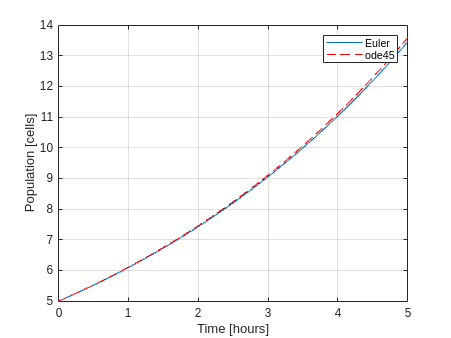

hold on;
plot(tout, yout, 'r--')
legend('Euler','ode45')